## Initialize

close
clearvars -except mapCD
addpath ..\od\OneDrive\matlab\myFunction\myftn\
fn = '..\od\OneDrive\matlab\RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

load ..\od\OneDrive\matlab\RawData\'1T-TaS2(point defect)'\grd.mat grd

## Tuning Parameter Setting

indLatts(:,:,1) = [2 54 53; 1 30 66];
shif_xys(:,:,1) = [0 -2 0;0 1 0];
indLatts(:,:,2) = [2 54 53; 1 30 66];
shif_xys(:,:,2) = [0 -2 0;0 1 0];

## DataProcessing

for iph = 1:2
    line_info =grd.line_info(iph,:,:);
    I_P__C = constructBases(line_info);
    szZ = size(mapCD.dt(iph).Z);
    a = consturctGrid(I_P__C,line_info,szZ);% less tuned coordinate
    b = a.latticeFineTune(indLatts(:,:,iph),shif_xys(:,:,iph));% more tuned coordinate
    as(iph) = a;
    bs(iph) = b;
end
abs = [as;bs];

## Visualization

validation check of the parameter

### Front Handles

iph = 1

iph = 1

### Drawing


% visualize(Z,a)

figureSetting

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

Background Image

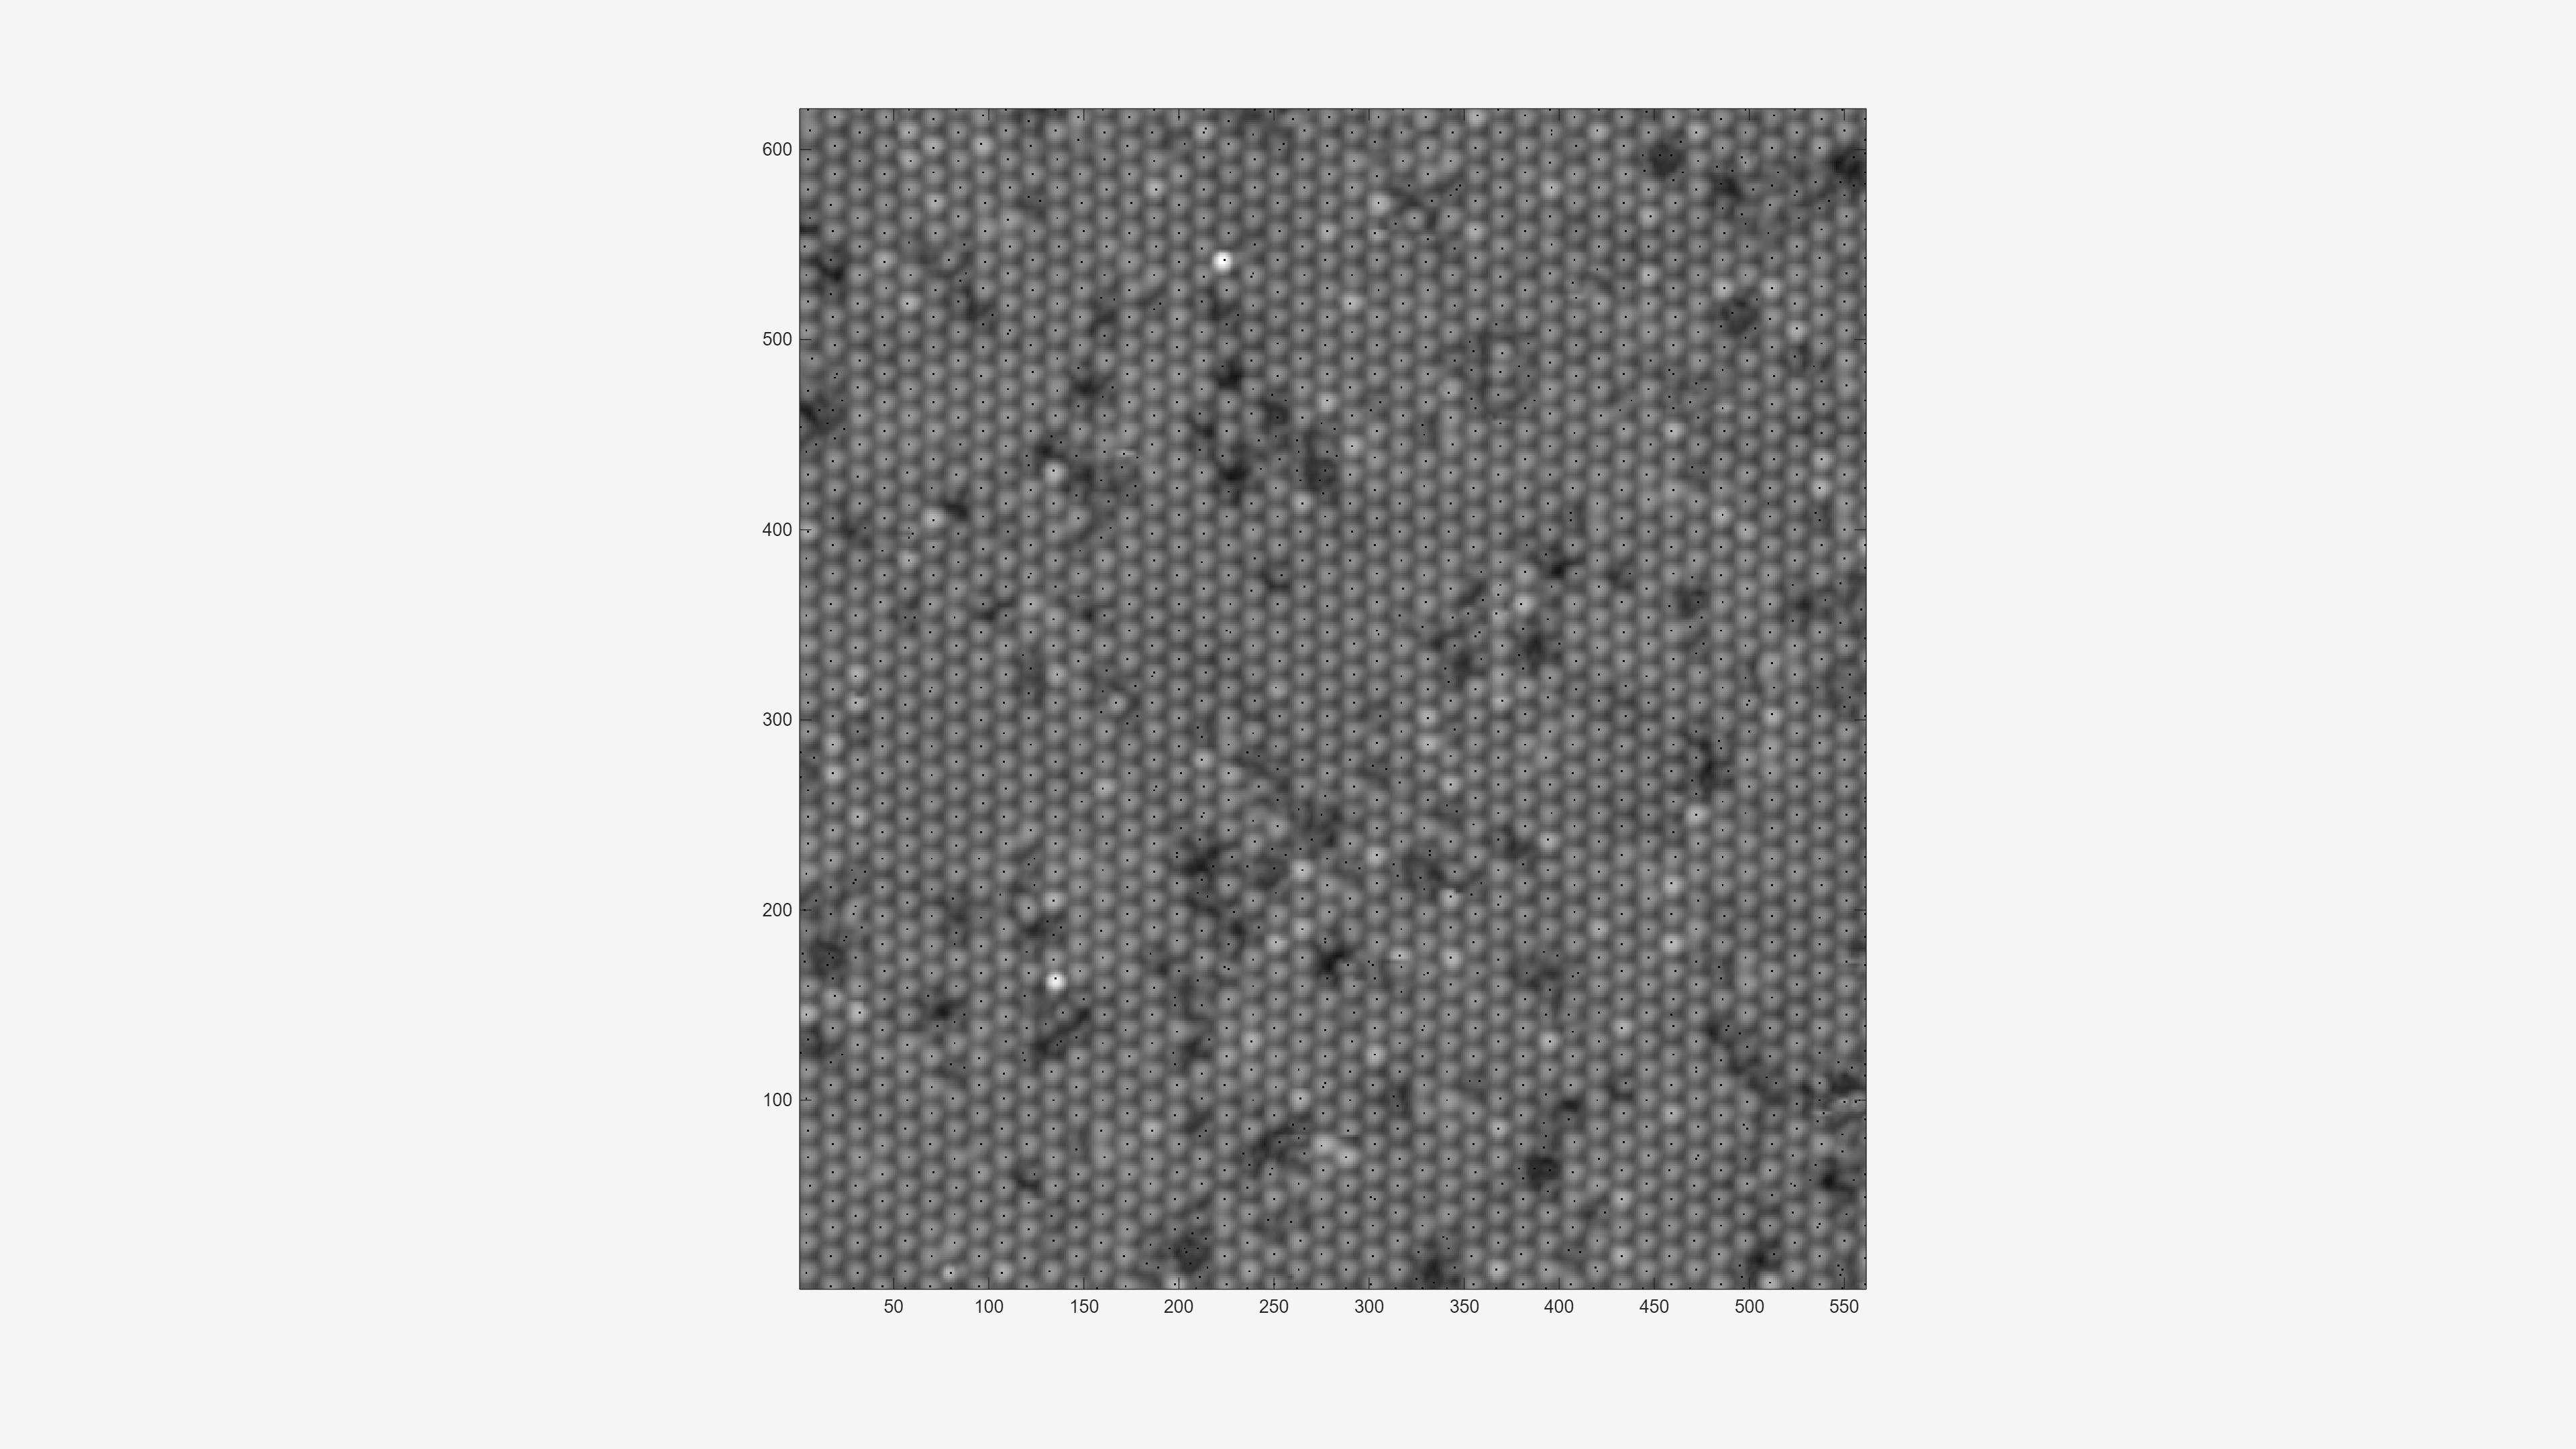

Z = mapCD.dt(iph).Z;
BW = imregionalmax(Z,8);
Z = Z.*~BW;
views(Z);
colormap gray;

pZ = findobj('Type','image');

3 points

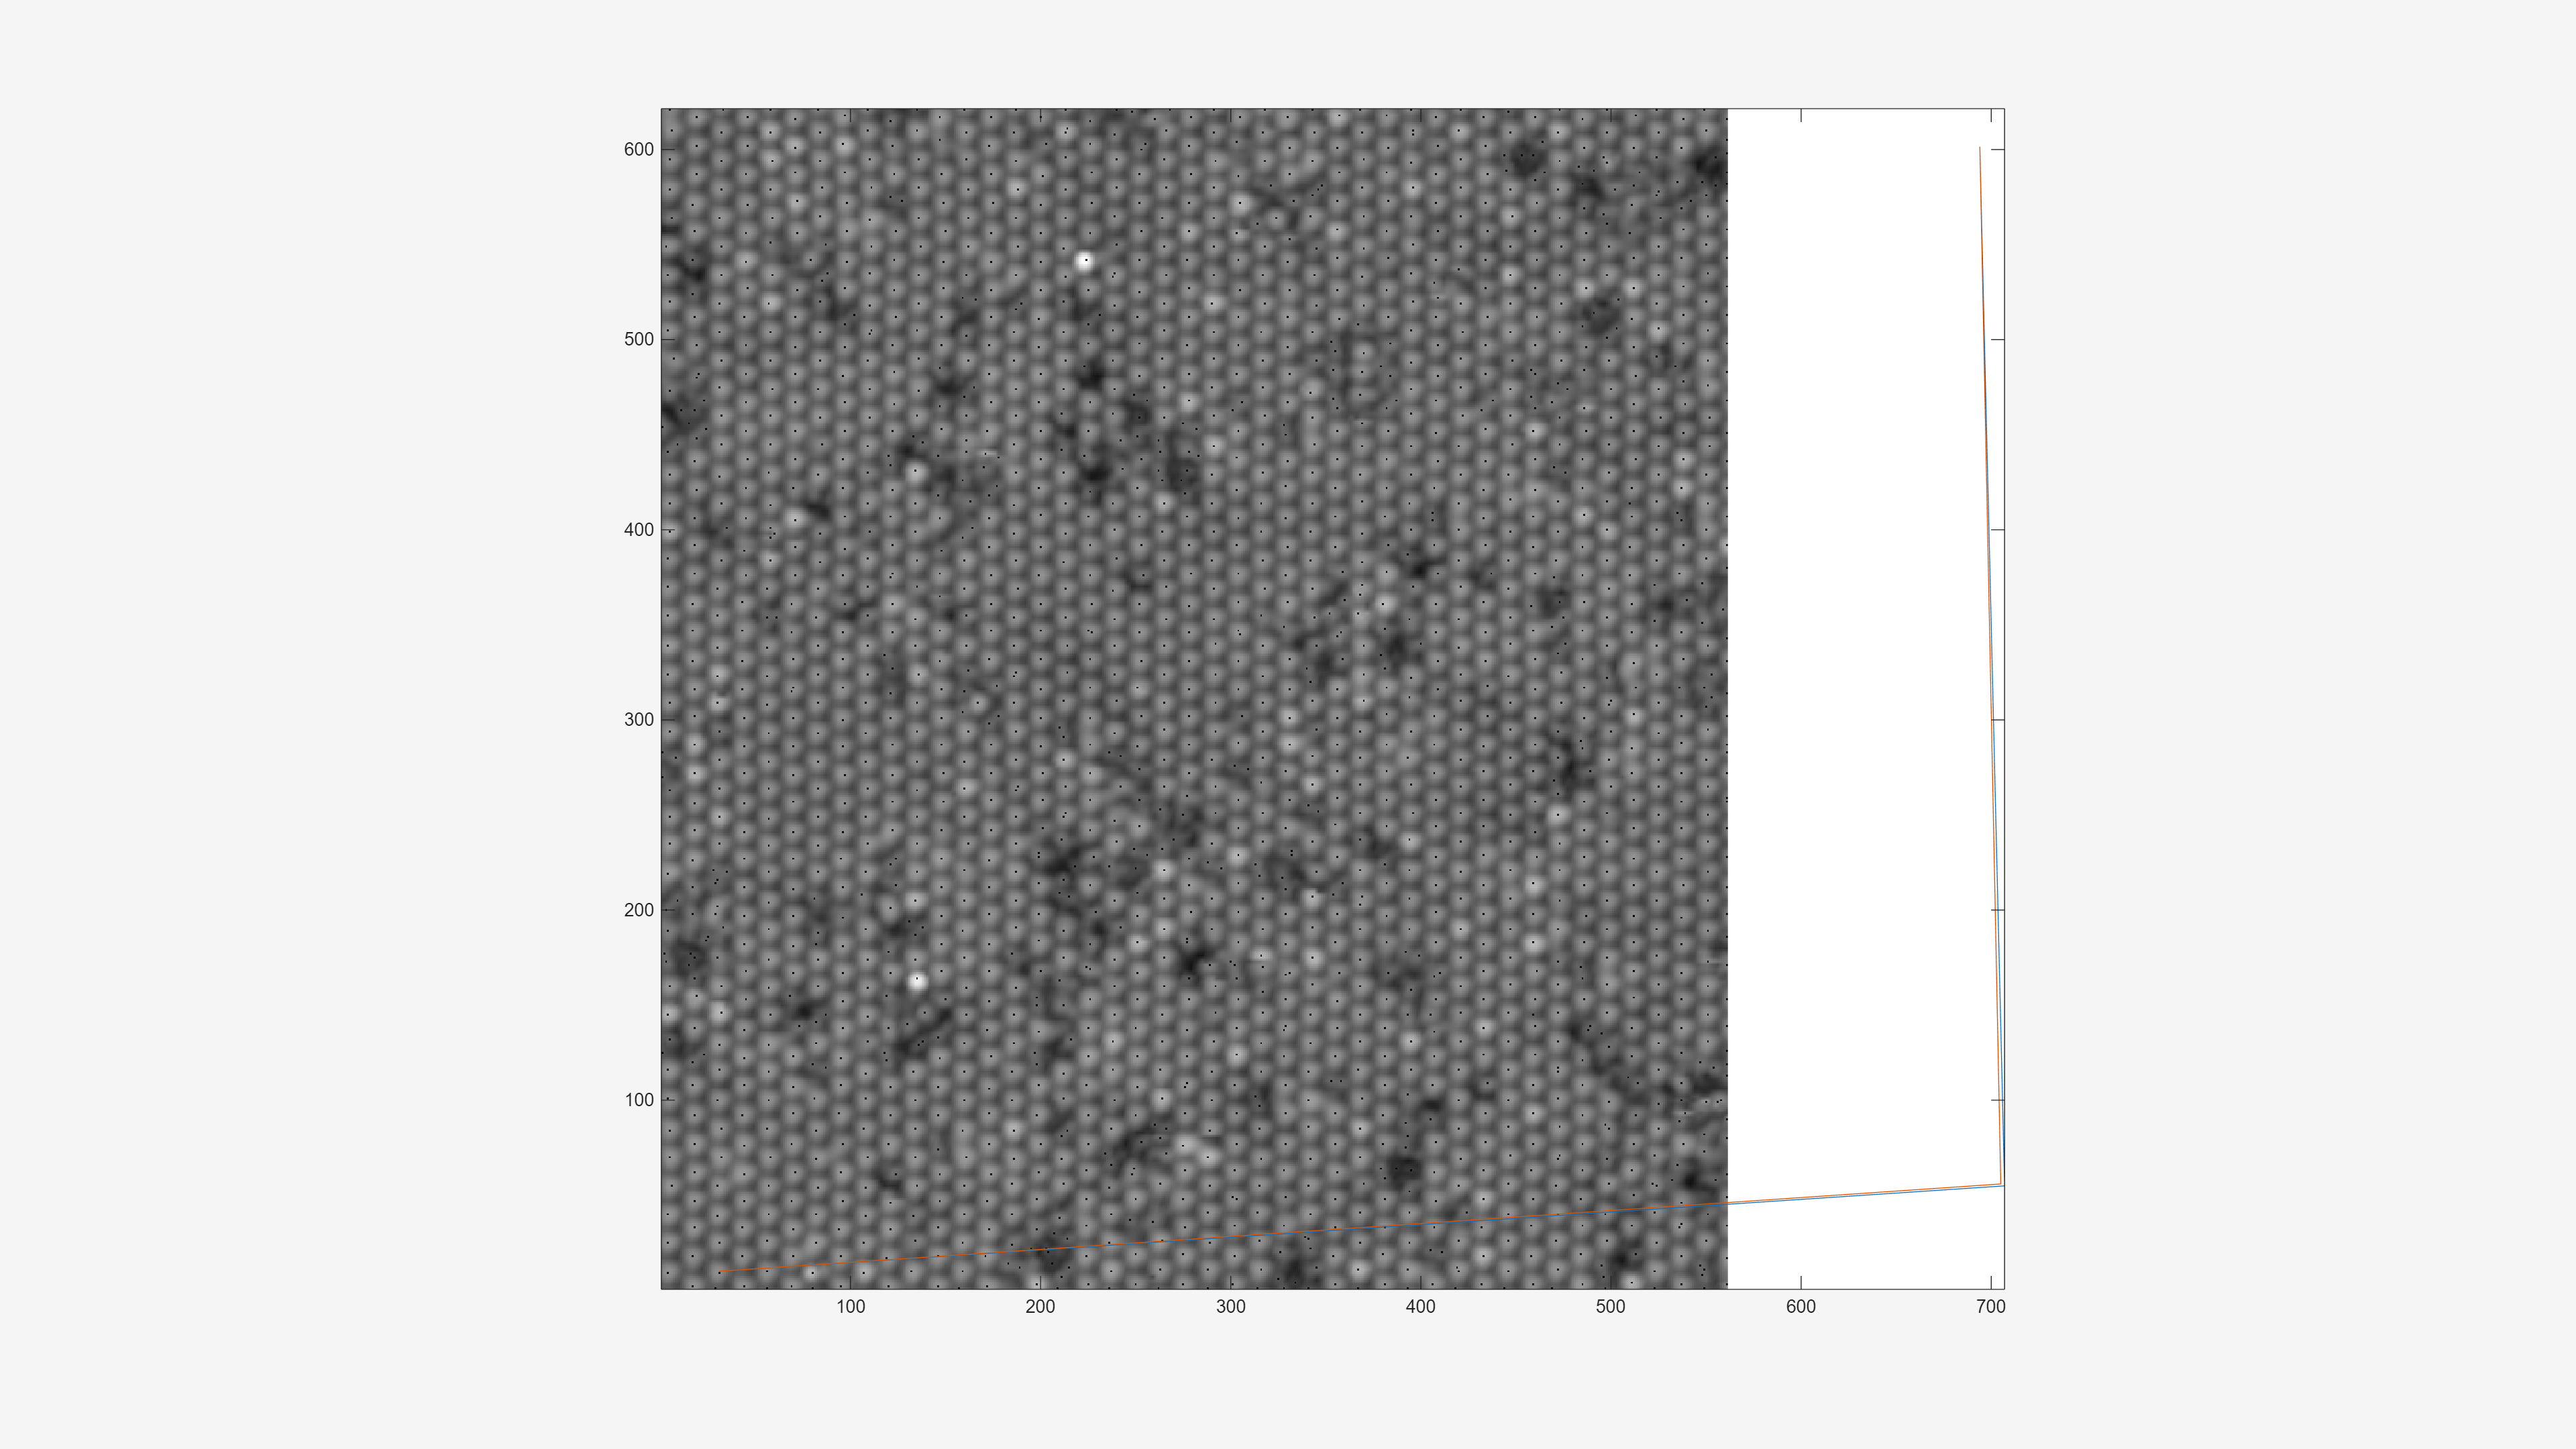

hold on
p3s(:,:,1) = as(1).oB2pC(indLatts(:,:,1));
p3s(:,:,2) = p3s(:,:,1) + shif_xys(:,:,iph);
for iba = 1:2
    plot(p3s(1,:,iba),p3s(2,:,iba))
end
hold off

Lattice

hold on
clrs = [1 0 0;0 1 0]

clrs =      1     0     0
     0     1     0


abs

abs = 2×2 grid2d array with properties:
    offset_stdpts
    a1_stdpts
    a2_stdpts
    sz_stdpts
    clr_a1
    clr_a2
    clr_faceWindow
    clr_edgeWindow
    augMat
    baryBss
    inLatt
    inGrid


for iba = 1:2
    pLs(iba) = abs(iba,iph).pLatticeWin;
    pLs(iba).Color = clrs(iba,:);
    pLs(iba).Marker ="."
end

ans = 'reCalculated'

xy =     5.0000   10.0000
    5.0000   24.9750
    5.0000   39.9500
    5.0000   54.9250
    5.0000   69.9000
    5.0000   84.8750
    5.0000   99.8500
    5.0000  114.8250
    5.0000  129.8000
    5.0000  144.7750
    5.0000  159.7500
    5.0000  174.7250
    5.0000  189.7000
    5.0000  204.6750
    5.0000  219.6500


ans = 'reCalculated'

ans = 'reCalculated'

pLs =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: '.'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 18 31 … ] (1×1784 double)
              YData: [10 24.9750 39.9500 54.9250 69.9000 84.8750 99.8500 114.8250 129.8000 144.7750 159.7500 174.7250 189.7000 204.6750 219.6500 234.6250 249.6000 264.5750 279.5500 294.5250 309.5000 324.4750 339.4500 354.4250 369.4000 … ] (1×1784 double)

  Show all pr

ans = 'reCalculated'

xy =     5.0831    9.9584
    5.1368   24.9066
    5.1904   39.8548
    5.2441   54.8030
    5.2977   69.7511
    5.3514   84.6993
    5.4050   99.6475
    5.4587  114.5956
    5.5124  129.5438
    5.5660  144.4920
    5.6197  159.4402
    5.6733  174.3883
    5.7270  189.3365
    5.7806  204.2847
    5.8343  219.2329


ans = 'reCalculated'

ans = 'reCalculated'

pLs =   1×2 Line array:

    Line    Line


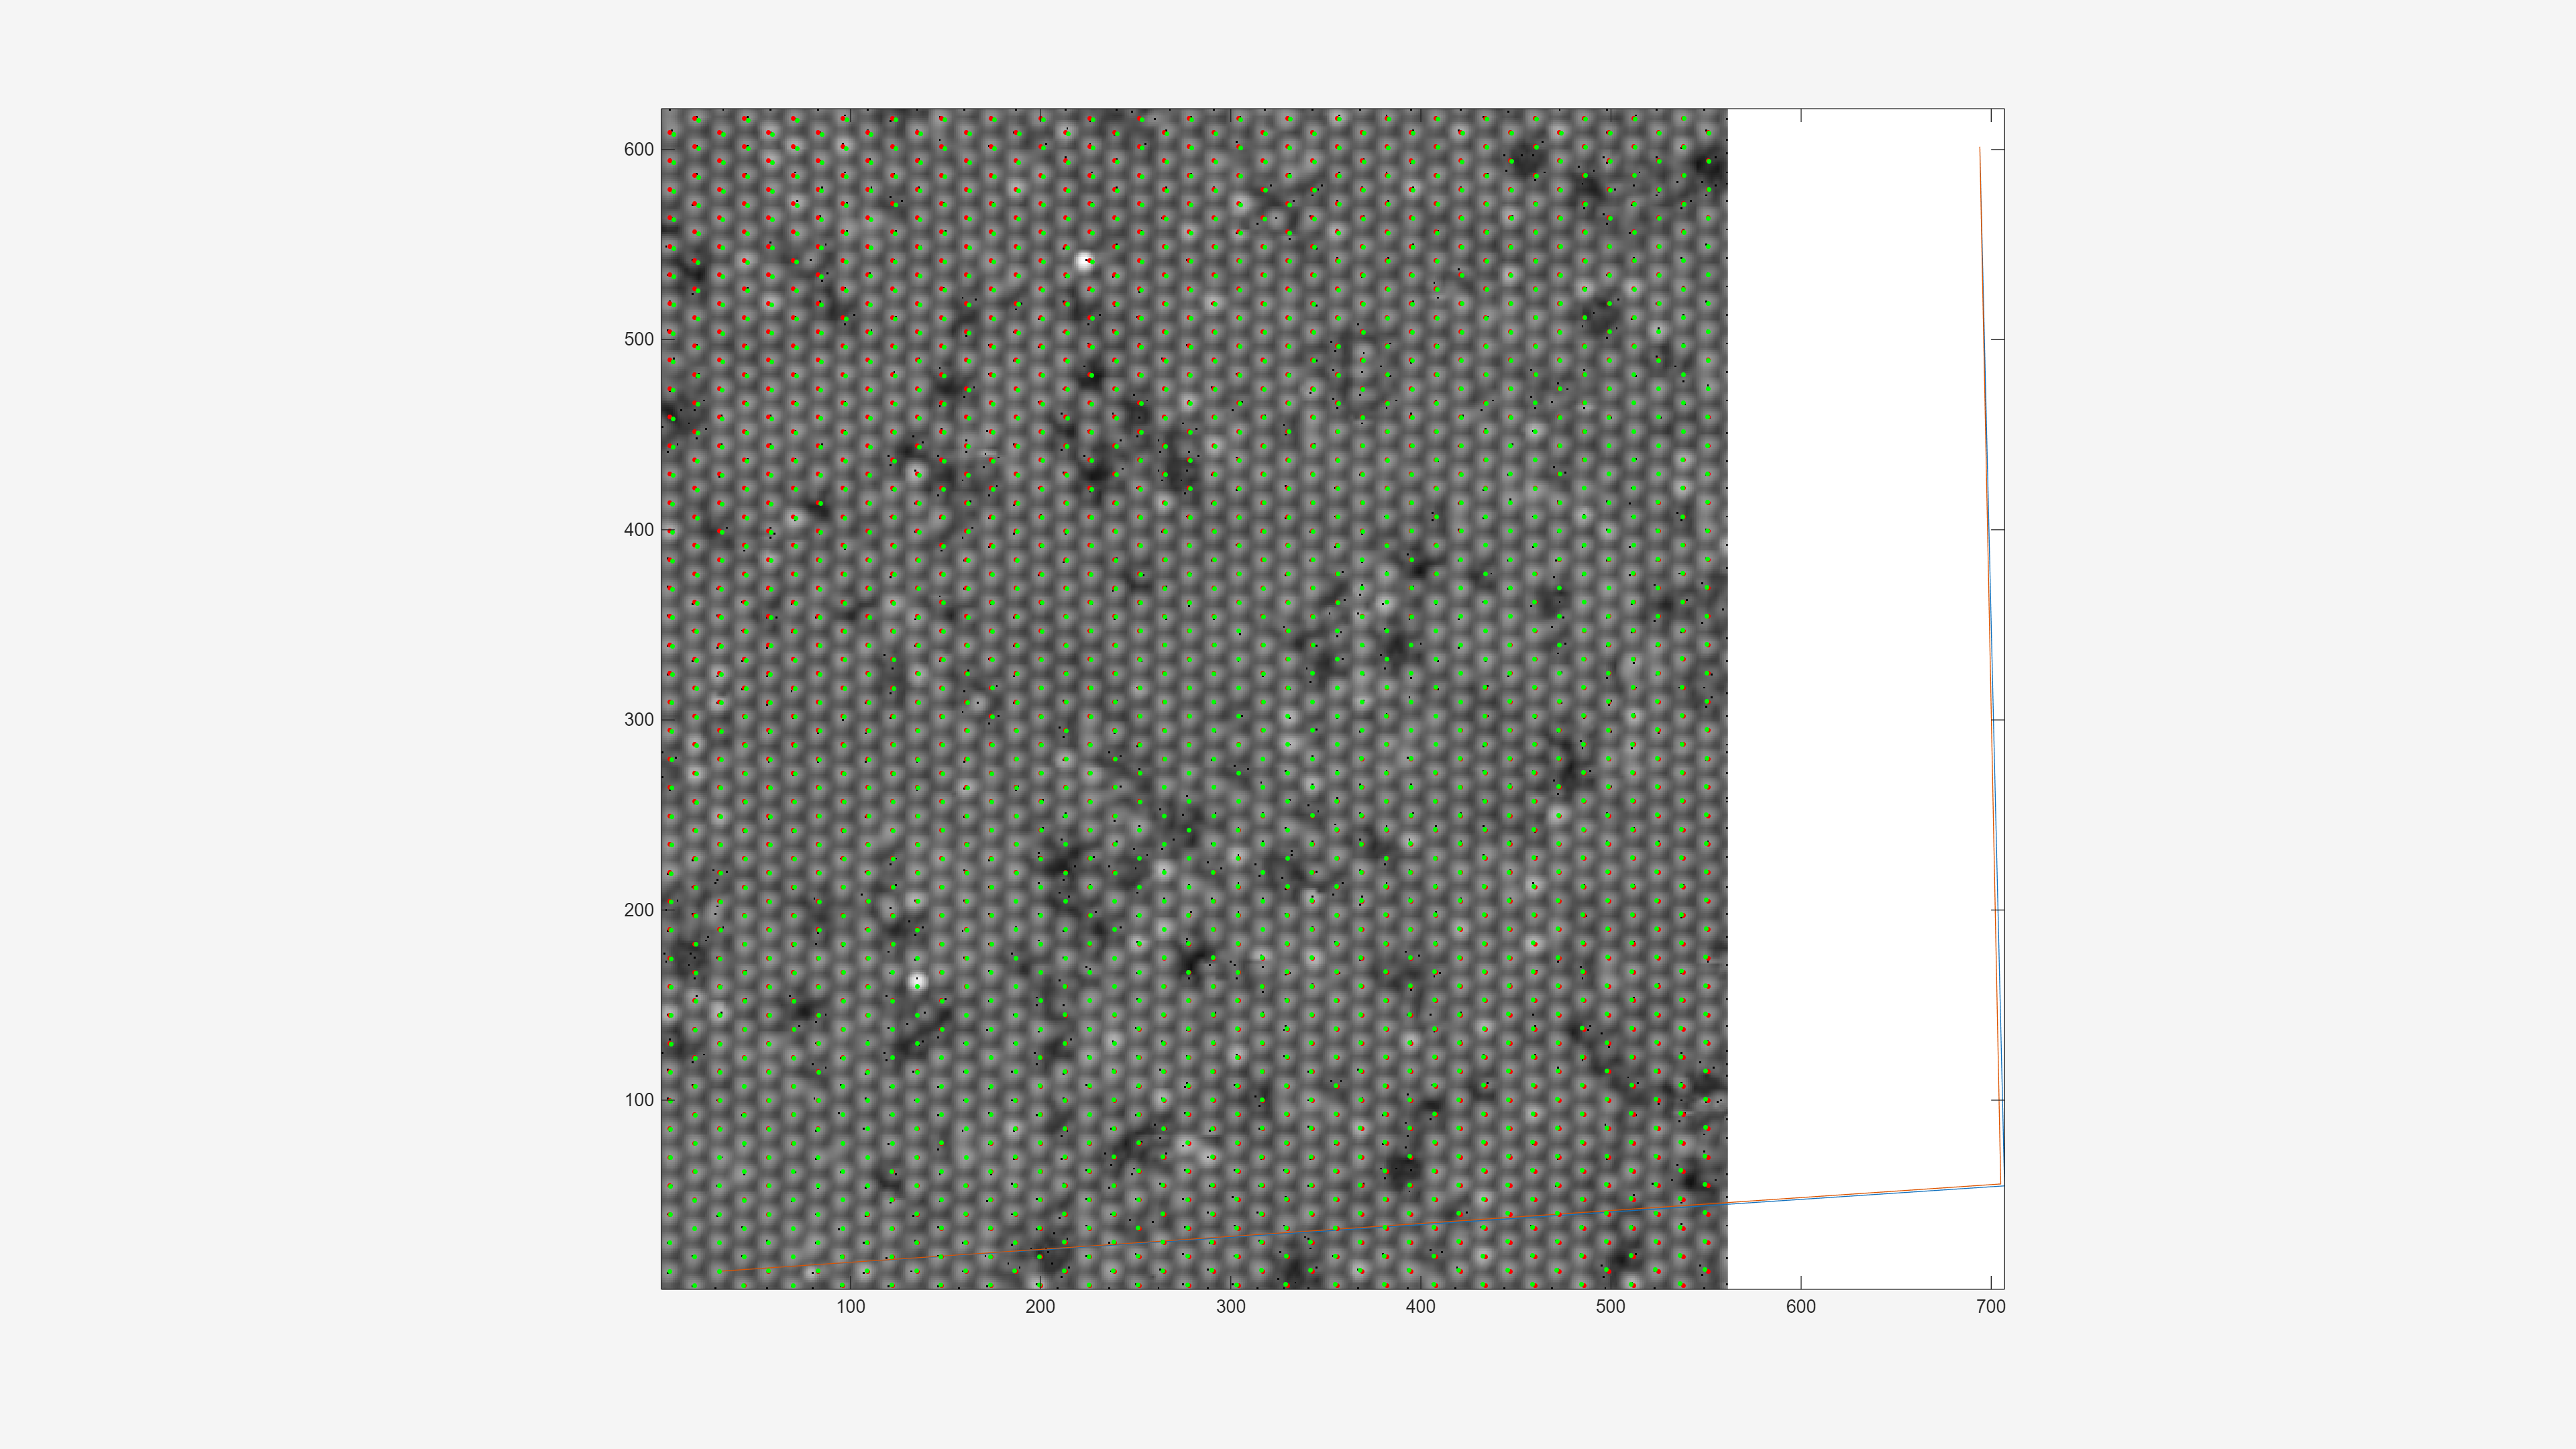

hold off

### Back Handles

pZ.Visible = true

pZ =   Image with properties:

           CData: [621×561 double]
    CDataMapping: 'scaled'

  Show all properties


pLs(1).Visible =   true

pLs =   1×2 Line array:

    Line    Line


pLs(2).Visible = true

pLs =   1×2 Line array:

    Line    Line


## Export final Coordinate

hd.from = currentScript;
hd.at = datetime;
% dt(1) =
% dt(2) = 

lattCoord.hd = hd

lattCoord = struct with fields:
    hd: [1×1 struct]


% lattCoord.dt = dt
% save RawData\'1T-TaS2(point defect)'\lattCoord.mat lattCoord

define  frequently called

% iph = 2
% line_info =grd.line_info(iph,:,:)
% Z = mapCD.dt(iph).Z;
% BW = imregionalmax(Z,8);
% Z = Z.*~BW;

Define new vector basis

% 
% I_P__C = constructBases(line_info);

Construc grid2d instance

% a = consturctGrid(I_P__C,line_info,Z);
% visualize(Z,a);

define 3 points

% indLatt = [2 54 53; 1 30 66]
% fcs_xy = a.oB2pC(indLatt)
% shif_xy = [0 -2 0;0 1 0]
% fcs_xy_shifted = fcs_xy + shif_xy
% hold on
% plot(fcs_xy(1,:),fcs_xy(2,:),'bo-')
% plot(fcs_xy_shifted(1,:),fcs_xy_shifted(2,:),'co-')
% hold off

% b = a.latticeFineTune(indLatt,shif_xy)
% hold on
% b.pLatticeWin
% hold off

% f = gcf
% redot = f.Children.Children(4)
% redot.Visible = 'off'


function visualize(Z,a)
gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";


hold on
a.pBases
hold off
hold on
p = a.pLatticeWin
p.Color = [1 0 0];
p.Marker ="o"
hold off
% hold on
% a.pGridlineWin
% hold off
f = gcf()
go = findobj(f,'type','image')
go.HitTest = 'off'
end

function a = consturctGrid(I_P__C,line_info,szZ)
a = grid2d();
a.a1_stdpts = I_P__C(:,1);
a.a2_stdpts = I_P__C(:,2);
a.offset_stdpts = line_info(:,1,:);
a.sz_stdpts = szZ;
end

function I_P__C = constructBases(line_info)
%P: pixel Coord
%B: line profile Coord
%C: lattice Coord
%Target: I_P__C
b1_x = (line_info(:,2,1) - line_info(:,1,1)) / (line_info(:,3,1)-1);
b2_y = (line_info(:,2,2) - line_info(:,1,2)) / (line_info(:,3,2)-1);
I_P__B = [b1_x 0;0 b2_y];
I_B__C = [1 0;-1/2 1];
I_P__C = I_P__B*I_B__C;
end